# Feedback Controls Course Project

Spring 2026

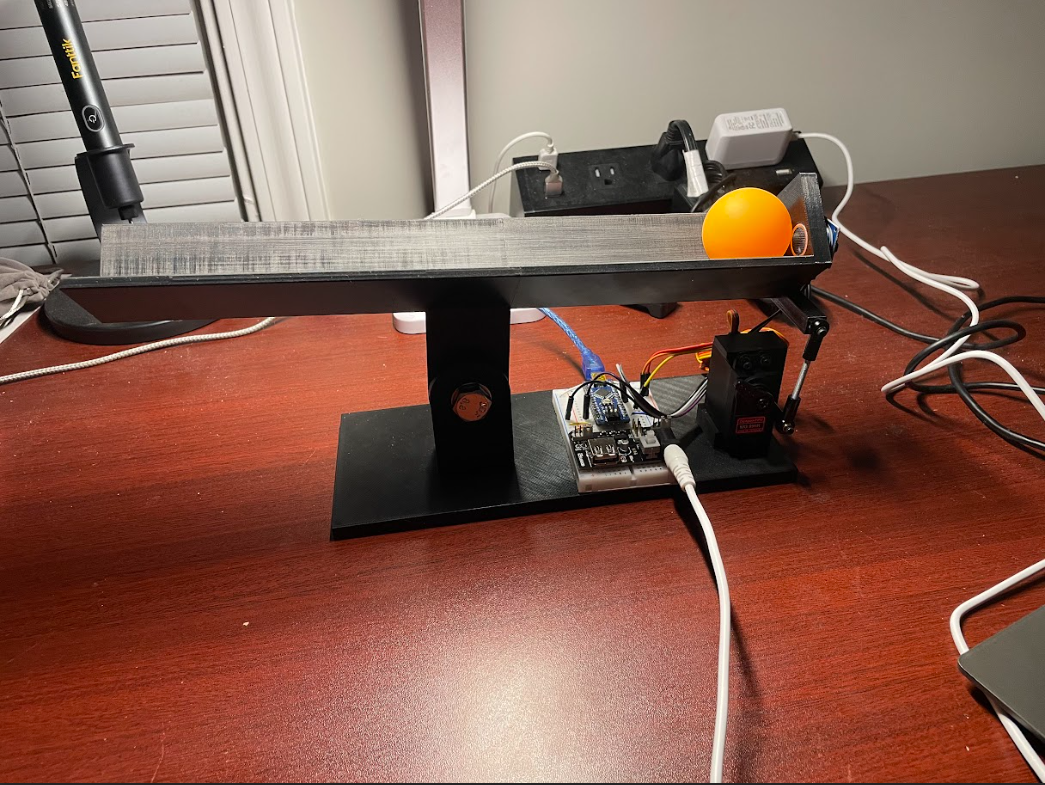 

### Considered for a 100%

## Checkpoint 1: *1 DoF Ball and Beam Control System*

#### Background

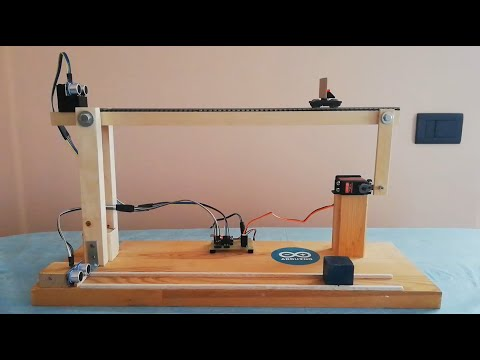

Figure 1. Motivational Photograph  

The goal of this project is to design and implement a 1-degree-of-freedom ball-and-beam feedback control system capable of stabilizing a ping pong ball at a specific setpoint. The system consists of a 30 cm slotted track mounted to a high-torque servo motor, which serves as the primary actuator to tilt the beam. An HC-SR04 ultrasonic distance sensor is mounted at one end of the beam to provide feedback on the ball’s position. This setup creates a Golden Model, where the controller must continually adjust the beam angle to counteract the ball’s natural gravitational acceleration, effectively transforming a marginally unstable double-integrator system into a stable, precise positioning system.  

The ball and beam system originated in the mid-20th century as a laboratory experience to study open-loop instability. It gained traction in the 1960s as engineers like Katsuhiko Ogata used it to show the power of state-space design. Since the 1960s, the system has changed from analog setups to digital implementations. Today, it’s still used popularly for testing PID and LQR algorithms and is popular in the DIY maker community due to low-cost microcontrollers.

Link for Katsuhiko Ogata’s textbook on controls: [https://plcsitemiz.wordpress.com/wp-content/uploads/2009/03/modern-control-engineering-kogata-3rd-edition.pdf](https://plcsitemiz.wordpress.com/wp-content/uploads/2009/03/modern-control-engineering-kogata-3rd-edition.pdf) 

Existing projects similar to a 1DoF ball and beam system usually fall into two categories: low-cost open source implementations and higher-end industrial training systems. For the industrial side, the Quansar Ball and Beam system is a popular choice for research universities. It uses rotary encoders and carbon fiber rods to minimize friction and non-linearity. In contrast, the DIY community uses 3D-printed mounts and standard hobbyist servos. These projects often use either ultrasonic or IR sensors for feedback, giving the stable closed-loop control for consumer-grade setups.

Link to Quansars Ball and Beam system: [https://www.quanser.com/products/ball-and-beam/](https://www.quanser.com/products/ball-and-beam/)

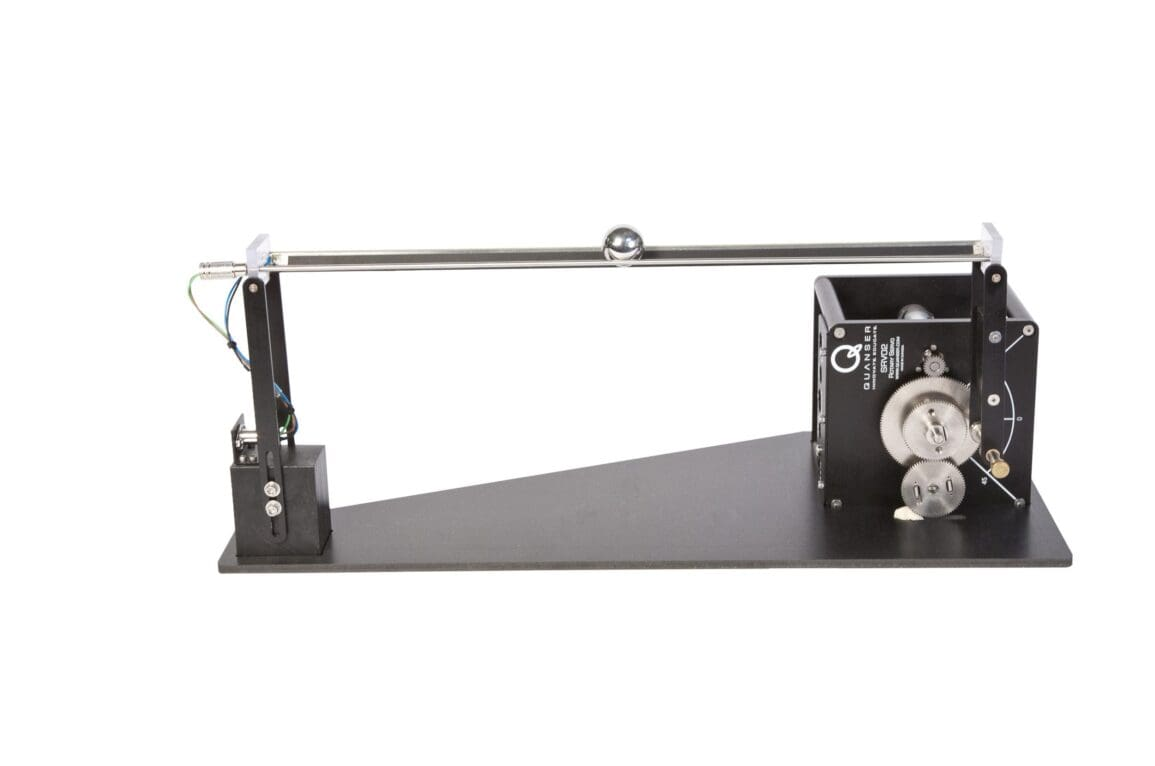

Figure 2. Quansar Ball and Beam System

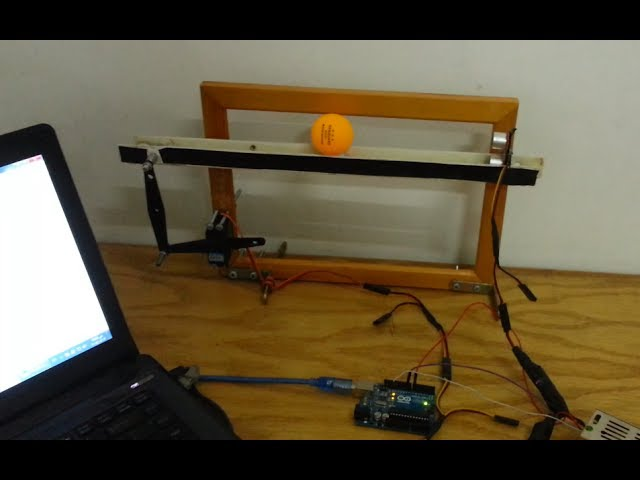

Figure 3. Example DIY System

A figure describing the behavior of the system is below:

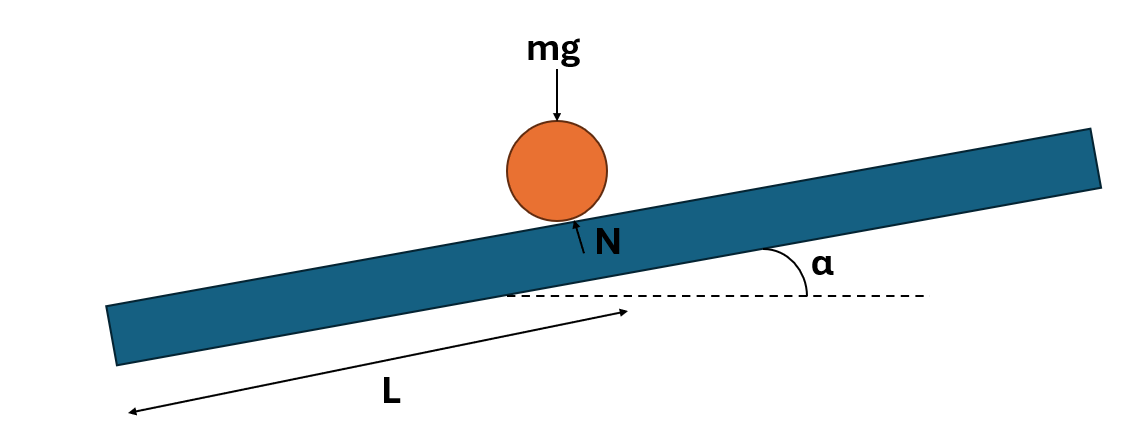

Figure 4. System Behavior Model

The parameters of the system are as follows:

- Beam length (L): 0.3 m

- Ball mass (m): 0.0027 kg

- Ball radius (r): 0.02 m

- Ball moment of inertia (J): $\frac{2}{3}MR^2$

- Gravitational acceleration (g): 9.81 m/s^2

- Ball position (R): Variable

- Beam angle (α): Variable

The ball moves because gravity pulls it down the slope created when the motor tilts the beam. The system's equation of motion is given as follows:


$$\left(\frac{J}{R^2 }+M\right)\ddot{r} +\textrm{Mgsin}\left(\alpha \right)-\textrm{Mr}{\left(\dot{\alpha} \right)}^2 =0$$


The equation of motion is comprised of three terms: The inertial term $\left(\frac{J}{R^2 }+M\right)\ddot{r}$, which accounts for the energy required to make the ball both rotate and translate, the gravity term $\textrm{Mgsin}\left(\alpha \right)$, which is the force pulling the ball, and the centrifugal term $\textrm{Mr}{\left(\dot{\alpha} \right)}^2$, which is typically neglected because the beam moves relatively slowly.

Linearizing this equation around the point where the beam is level (ɑ = 0) and using small-angle approximation (sin(ɑ) = ɑ):


$$\left(\frac{\frac{2}{3}MR^2 }{R^2 }+M\right)\ddot{r} =-\textrm{Mg}\alpha \Longrightarrow \frac{5}{3}M\ddot{r} =-\textrm{Mg}\alpha \Longrightarrow \ddot{r} =-\frac{3}{5}g\alpha$$


Taking the Laplace transform gives the plant model:


$$G\left(s\right)=\frac{R\left(s\right)}{A\left(s\right)}=\frac{-5\ldotp 886}{s^2 }$$


References:

- Quansar Consulting Inc. (2012). *Ball and Beam Participant Manual*

- Ogata, K. (2010). *Modern Control Engineering.* 5th Ed. Prentice Hall

The nominal model derived here is an idealization. It assumes a perfectly rigid beam, a uniform hollow sphere, and zero air resistance or mechanical friction. In contrast, the calibration model will account for hardware nonlinearities. This includes the mechanical deadband in the servo motor gears, the rolling resistance of the slotted track, and the measurement noise in the sensor. Calibration will involve mapping the raw sensor voltage to an accurate distance and finding the real zero angle where the ball remains stationary.

The system currently fails on its own. This is because of the two poles at s = 0, meaning that this is a double integrator. Without any control, the ball has no home point and will accelerate indefinitely until it hits a physical limit. The figure below illustrates this: any angle tilt results in an exponential change in position over time.

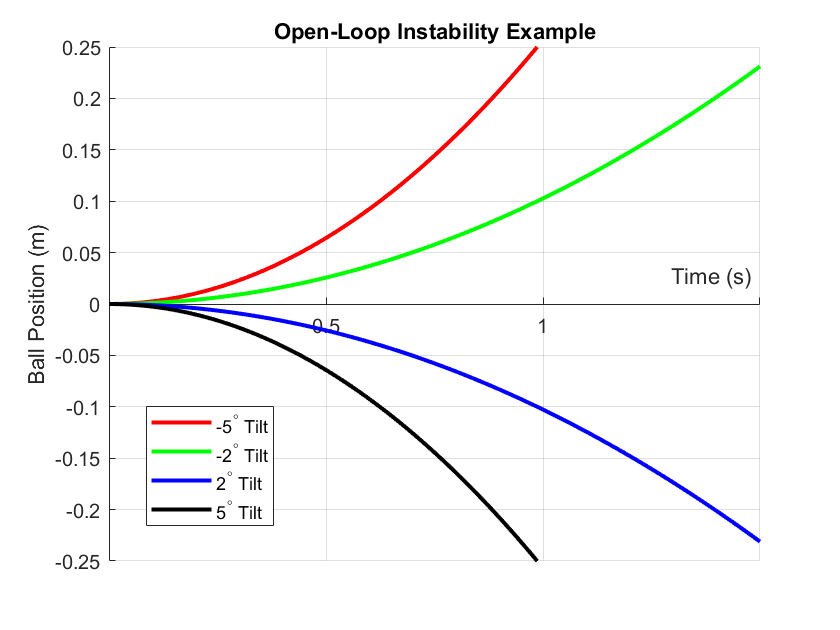

Figure 5. Instability of Open Loop Control

The model also assumes no friction. The controller will need to include friction as a D term to prevent the ball from oscillating forever. Beyond feedback control, certain structural changes can improve open-loop performance. Implementing a slotted track or V-groove adds passive lateral stability, preventing the ball from rolling off the sides. Additionally, using a ball with a higher moment of inertia would slow the natural acceleration, effectively making the system’s behavior less aggressive and easier for the controller to track.

#### Simulation

%Parameters
L = 0.3; % Beam length (m)
m = 0.0027; % Ball mass (kg)
r = 0.02; % Ball radius (m)
g = 9.81; % Gravitational acceleration (m/s^2)
J = (2/3)*m*r^2; % Ball moment of inertia (kg*m^2)

% Linearized plant gain: R_ddot = -(3/5)*g*alpha
K_plant = -(3/5)*g;  % = -5.886

%% Plant Transfer Function
% G(s) = R(s)/A(s) = -5.886 / s^2
num = K_plant;
den = [1 0 0];
G = tf(num, den);
disp('OL Transfer Function')

OL Transfer Function


G


G =
 
  -5.886
  ------
   s^2
 
Continuous-time transfer function.


sim('ball_beam_openloop')

ans =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [56x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


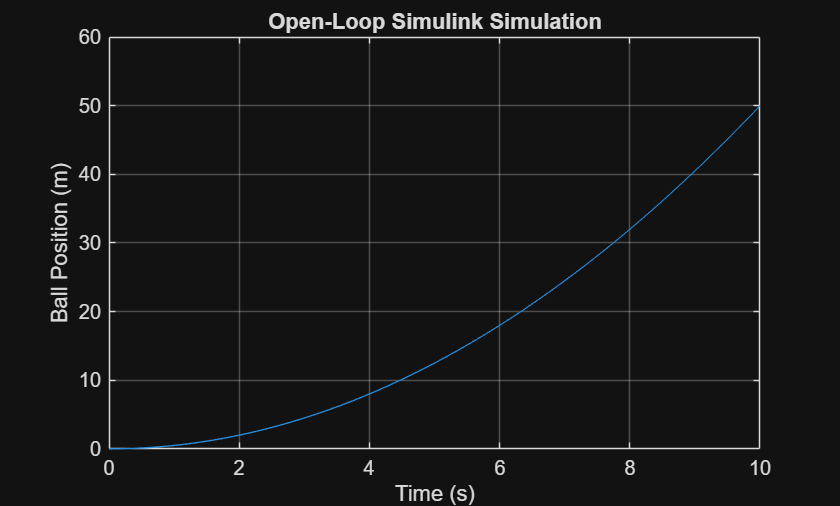


out = sim('ball_beam_openloop');
t_sim = out.simout.Time;
R_sim = out.simout.Data;

figure;
plot(t_sim, R_sim);
xlabel('Time (s)'); ylabel('Ball Position (m)');
title('Open-Loop Simulink Simulation');
grid on;

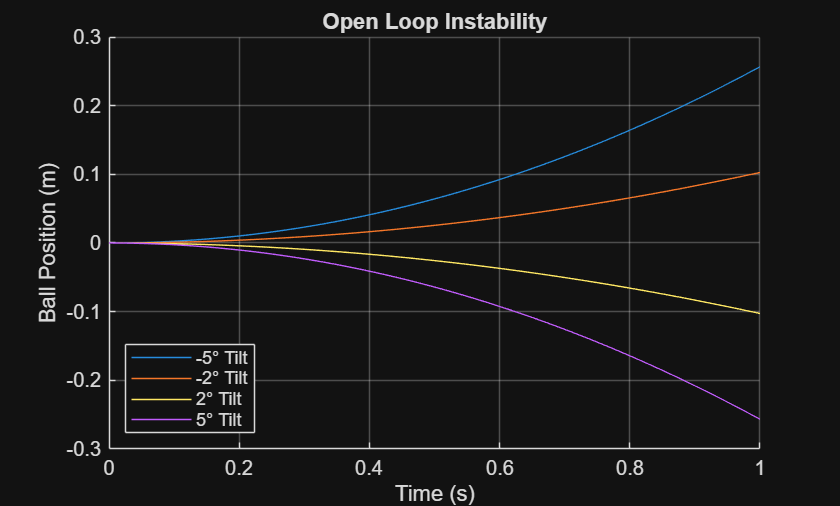

% Plots
t = linspace(0, 1, 500);
angles_deg = [-5, -2, 2, 5];  % degrees

figure;
hold on;

for i = 1:length(angles_deg)
    alpha = deg2rad(angles_deg(i));  % convert to radians
    % R_ddot = K_plant * alpha  =>  R(t) = 0.5 * K_plant * alpha * t^2
    R = 0.5 * K_plant * alpha * t.^2;
    plot(t, R);
end

xlabel('Time (s)');
ylabel('Ball Position (m)');
title('Open Loop Instability');
legend('-5° Tilt', '-2° Tilt', '2° Tilt', '5° Tilt', 'Location', 'southwest');
grid on;
hold off;

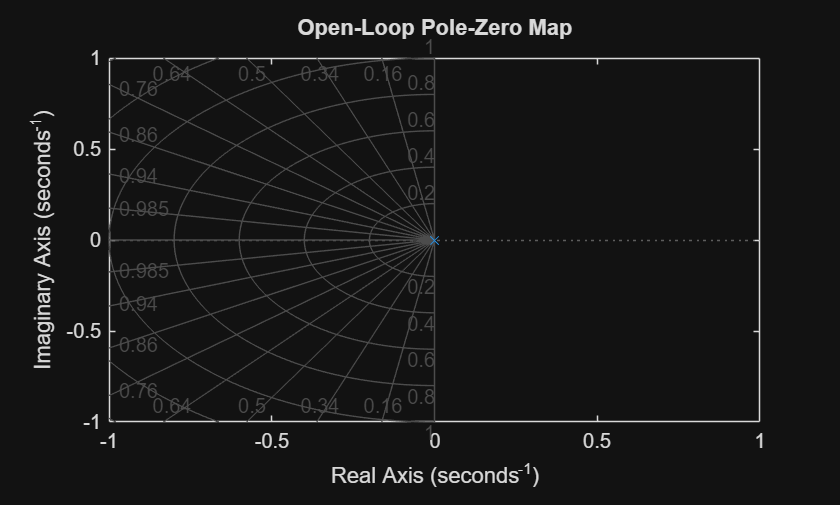


% Pole Zero Map
figure;
pzmap(G);
title('Open-Loop Pole-Zero Map');
grid on;

The open loop ball and beam system is inherently unstable, it has two poles at s = 0 in the plant transfer function G(s) = −5.886/s². This means that any non zero beam angle produces an acceleration on the ball with no restoring force. As shown in the simulation, even a small tilt of ±2° causes the ball to drift continuously, while larger angles like ±5° produce rapid runaway within one second. Without feedback, the system has no equilibrium point and the ball will accelerate until it reaches a physical boundary. This confirms that closed loop control is needed for stable operation.

## Checkpoint 2: Sensors, Actuators, and Signals

### Sensors

The ball and beam system requires measurement of the ball's position along the beam this is the only state directly measured. The beam angle is calculated from the servo movement commands. The HC-SR04 ultrasonic distance sensor is mounted to one end of the beam and measures the time of flight of a sound pulse to determine the ball's distance from the sensor.

From a practical perspective, the HC-SR04 emits a 40 kHz ultrasonic burst when triggered by a 10 microsecond high pulse on its trig pin. The echo pin then goes high for a time legnth proportional to the distance. The microcontroller measures this pulse width and converts it to distance. The sensor operates at 5V, which will be supplied by the arduino uno, and has a range of 2 to 400 cm with approximately 3 mm accuracy. The sample rate is limited to around 26 ms per reading (38.5 Hz) due to the internal timing. 

Physical limits: minimum detectable distance is 2 cm, maximum is 400 cm, and the beam constrains the needed range to 0 to 30 cm.

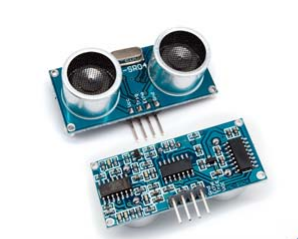

-  HC-SR04 Ultrasonic Sensor: [https://cdn.sparkfun.com/datasheets/Sensors/Proximity/HCSR04.pdf](https://cdn.sparkfun.com/datasheets/Sensors/Proximity/HCSR04.pdf)

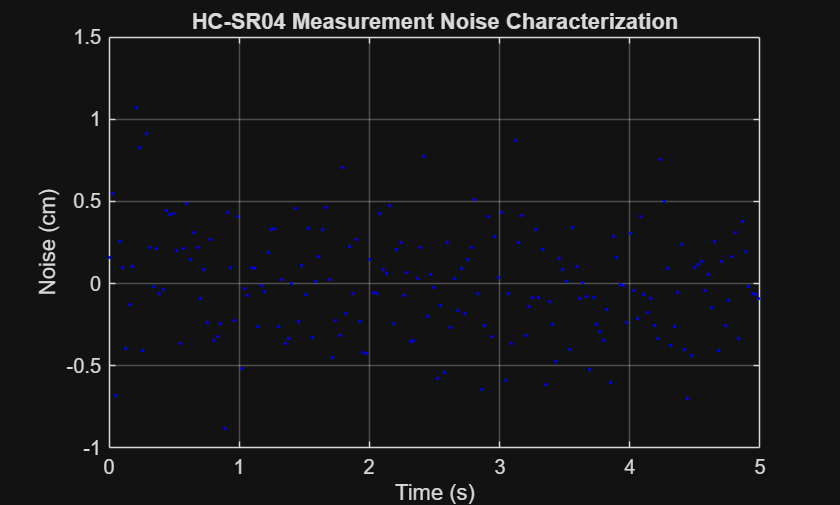

% Sensor parameters
sensor_range_min = 0.02; % minimum range for sensor(m)
sensor_range_max = 0.30; % beam length (m)
sample_time = 0.026;
sensor_noise_std = 0.003; % std dev noise (m)

% Distance conversion from pulse width
% distance = pulse_width * speed_of_sound / 2
speed_of_sound = 343;  % m/s at room temp
% Example: pulse_width = 0.001 s => distance = 0.1715 m

% Sensor noise model
t_noise = 0:sample_time:5;
noise = sensor_noise_std * randn(size(t_noise));

figure;
plot(t_noise, noise*100, 'b.', 'MarkerSize', 4);
xlabel('Time (s)'); ylabel('Noise (cm)');
title('HC-SR04 Measurement Noise Characterization');
grid on;

### Actuators

The beam angle is controlled by an MG996R servo motor. The servo receives a PWM signal at 50 Hz, with pulse widths between 1 ms ,0 degrees, and 2 ms ,180 degrees, commanding a specific angle. Since the servo is position controlled internally, the input to the plant is beam angle α, which maps directly to the controller output.

The MG996R operates at 5 to 7.2V and produces up to 9.4 kg cm of stall torque at 5V. 

Physical limits: angular range is 0 to 180 degrees, with the beam operating over a real world range of ±15 degrees around horizontal. 

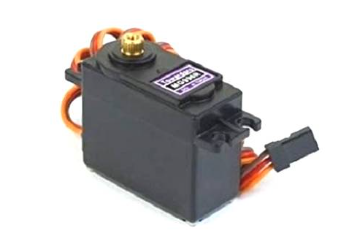

-  MG996R Servo Motor: [https://www.electronicoscaldas.com/datasheet/MG996R_Tower-Pro.pdf](https://www.electronicoscaldas.com/datasheet/MG996R_Tower-Pro.pdf)

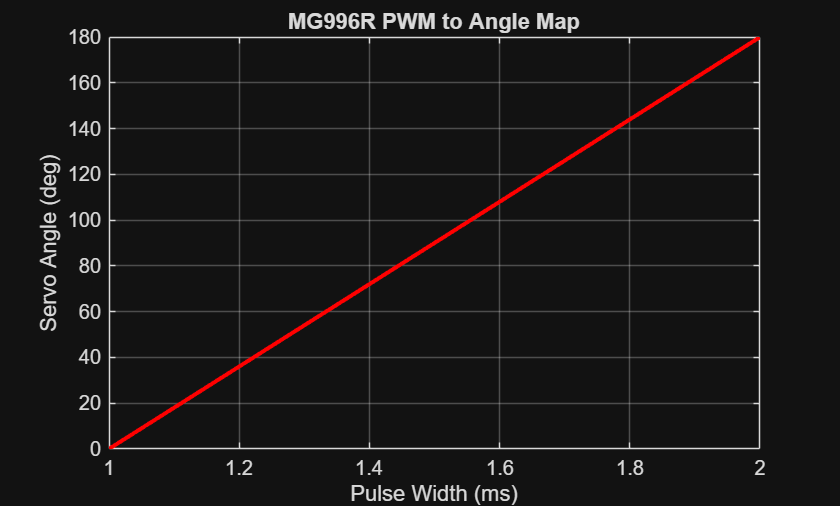

% Servo parameters
servo_voltage = 6.0;
stall_torque = 1.08;
no_load_speed = 6.28;
angle_min = -15;
angle_max = 15;
deadband_deg = 0.9;

% pulse width to angle
pulse_width = linspace(1, 2, 180);  % 1ms to 2ms
angle_deg = linspace(0, 180, 180);

figure;
plot(pulse_width, angle_deg, 'r', 'LineWidth', 2);
xlabel('Pulse Width (ms)'); ylabel('Servo Angle (deg)');
title('MG996R PWM to Angle Map');
grid on;

% Saturation limits for controller
alpha_max_rad = deg2rad(angle_max);
alpha_min_rad = deg2rad(angle_min);
fprintf('Actuator saturation: %.4f to %.4f rad\n', alpha_min_rad, alpha_max_rad);

Actuator saturation: -0.2618 to 0.2618 rad


### Signals

The main disturbance in this system is mechanical vibration from the servo motor and external movement. Sensor noise from the HC-SR04 is modeled as additive white Gaussian noise with standard deviation of ±3 mm. No unit scaling gains are needed between the sensor and controller since both operate in meters and radians. The servo input requires a conversion from degrees to PWM, mapping the controller output angle to a pulse width in the range 1 to 2 ms.

% Noise model (additive Gaussian on sensor output)
noise_std = 0.003;  % (m)

% Disturbance model (small angle impulse, e.g. table bump)
disturbance_amplitude = deg2rad(1);  % 1 degree equivalent disturbance

rad_to_deg_gain = 180/pi;

% angle (0-180 deg) to pulse width (1-2 ms)
% pulse_width_ms = 1 + (angle_deg / 180)
fprintf('Unit gain (rad to deg): %.4f\n', rad_to_deg_gain);

Unit gain (rad to deg): 57.2958


fprintf('PWM formula: pw = 1 + (angle_deg / 180) ms\n');

PWM formula: pw = 1 + (angle_deg / 180) ms


### Controller

For simulation purposes, a proportional controller (Kp = 1) is used as a placeholder. The full controller will be designed in Checkpoint 3 using Root Locus and frequency domain methods. In hardware, the controller will run on a microcontroller that reads the HC-SR04 output, computes the error from the setpoint, and commands the MG996R via PWM.

Kp = 1;  % Dummy proportional gain for Golden Model
C = tf(Kp)


C =
 
  1
 
Static gain.


### A Golden Model

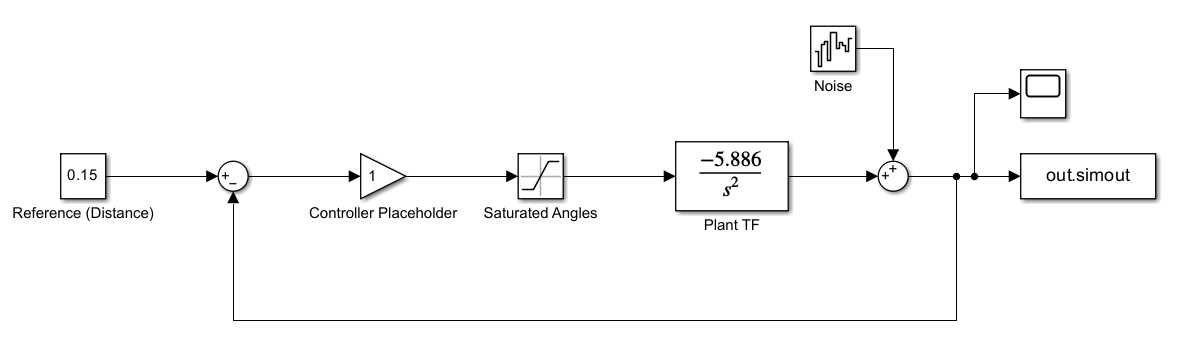

Figure 6. Golden Model

### Simscape Simulation

The simscape model included below constructs a representation of the feedback control system for this project. This model includes parameters for the slotted track and ping pong ball, as well as nonlinearities such as measurement noise of the HC-SR04 sensor and saturation limits of the MG996R motor. This simulation shows that the proposed controller can stabilize the double-integrator system and center the ball, giving the validation to continue with physical fabrication.

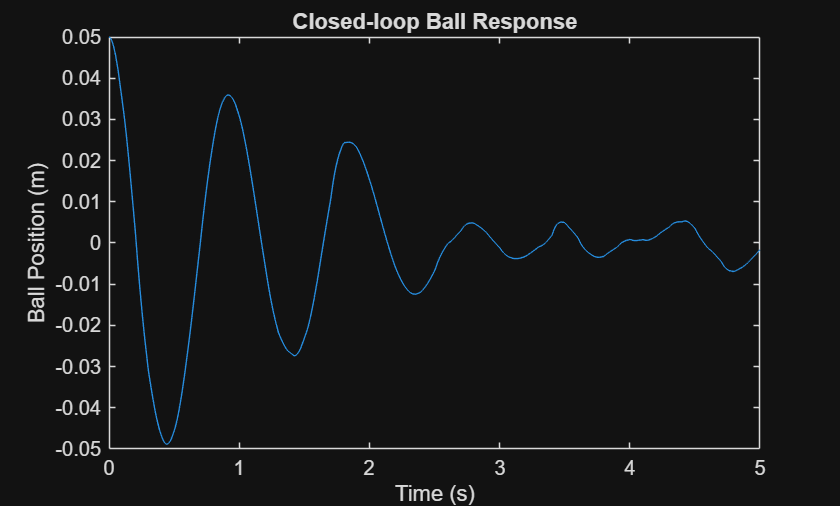

out = sim('ball_beam_sim');
plot(out.ball_data.Time, out.ball_data.Data);
xlabel('Time (s)');
ylabel('Ball Position (m)');
title('Closed-loop Ball Response');

### 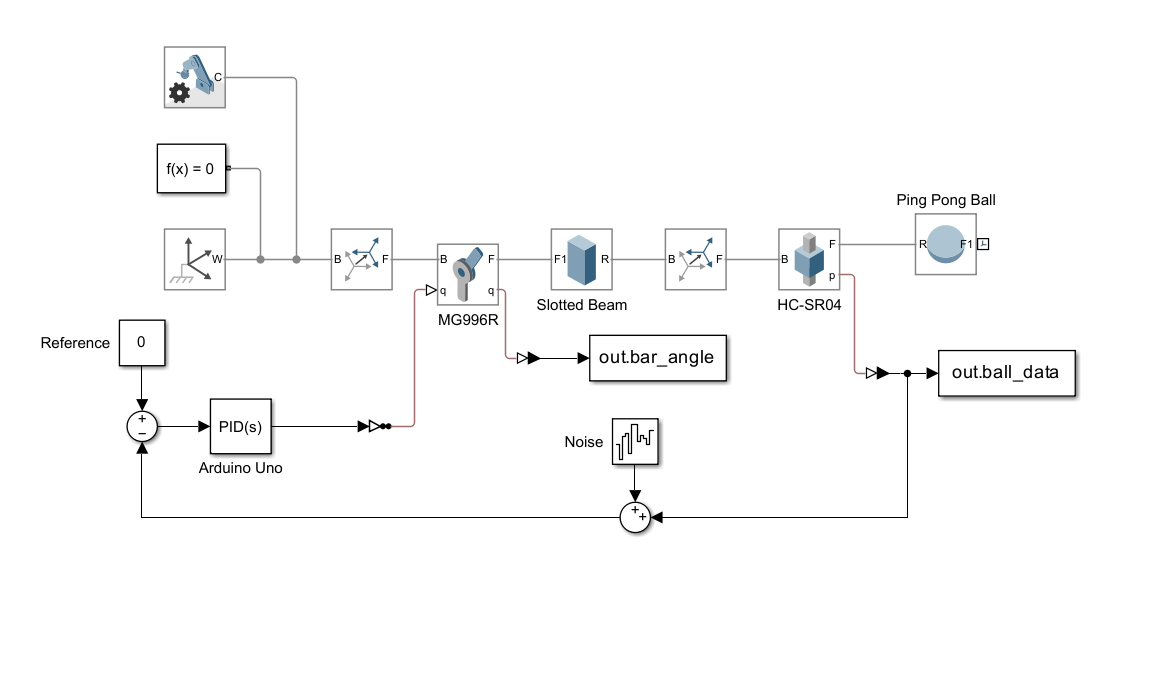

### Hardware Time

The image below describe the current design of the 1DoF ball balancing system. The physical plant uses an end-actuated crank-rocker linkage design to control the slotted track angle. The beam is perfectly horizontal when the servo is at its 90 degree midpoint. The central pivot is supported by a dual-bearing tower to allow smooth and free rotation. The slotted track and base will be PLA 3D printed.

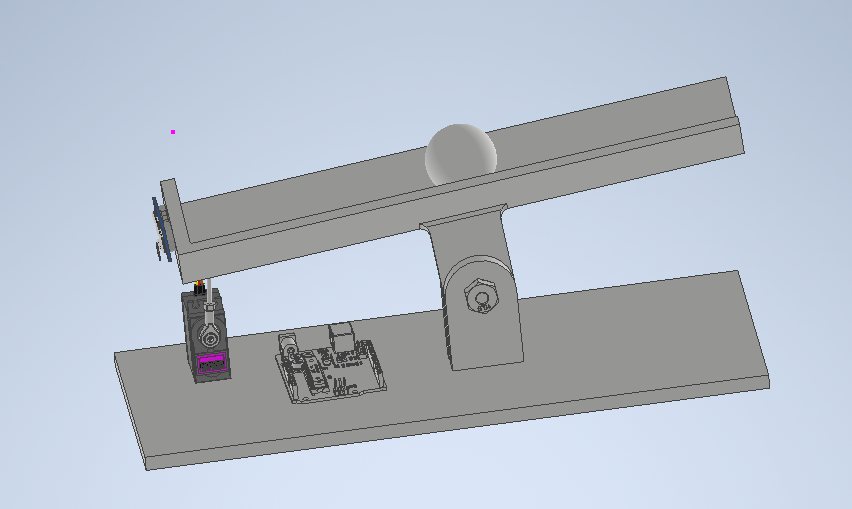

Figure 7. Physical Plant Design

## Checkpoint 3: Controller Design

### Closed-Loop Goals

The control objective is to stabilize the ball at a commanded position along the beam with zero steady state error and minimum achievable overshoot. Given the physical constraints of the MG996R servo (±15 degree saturation, ~0.9 degree deadband) and HC-SR04 noise (±3 mm), we have selected the following time domain targets:

- Overshoot: < 5%

- Settling time: < 3 seconds

- Steady-state error: 0 m

We have chosen a PD controller. The double integrator plant guarantees zero steady-state error to a step input without requiring an integrator in the controller. The derivative term introduces a zero that improves damping and pulls closed loop poles into the left half plane.

### Time Domain

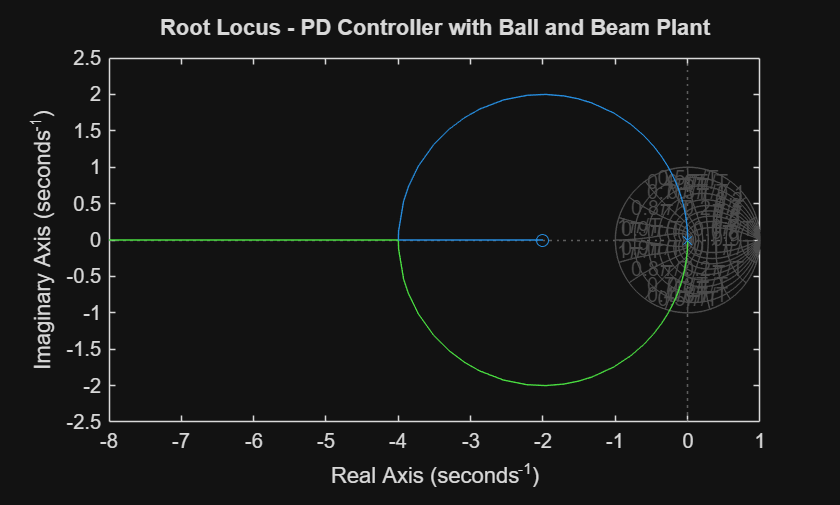

% System Parameters
L = 0.3; m = 0.0027; r = 0.02; g = 9.81;
J = (2/3)*m*r^2;
K_plant = -(3/5)*g;

% Plant
G = tf(K_plant, [1 0 0]);

% PD Controller: C(s) = Kp*(1 + Td*s)
% Place zero at s = -2 for good damping (tunable)
Td = 0.5;    % Derivative time constant
Kp = 1;      % Initial gain (tuned via root locus)

C_PD = Kp * tf([Td 1], 1);  % Kp*(Td*s + 1)

% Open-Loop TF for Root Locus
L_OL = C_PD * (-G);  % = Kp * 5.886 * (Td*s + 1) / s^2

figure;
rlocus(L_OL);
title('Root Locus - PD Controller with Ball and Beam Plant');
grid on;
zgrid;  % overlays damping ratio and natural frequency lines

From the root locus, the closed loop poles are placed to achieve a damping ratio of ζ ≥ 0.8, corresponding to overshoot ≤ 1.5%. The derivative zero at s = −2 pulls the locus branches into the left half plane, providing stable closed loop behavior for a range of gains. The gain Kp is selected to place the dominant poles at the desired natural frequency.

% Pole Placement via Root Locus

zeta_target = 0.8;
wn_target   = 3.0;

% Desired dominant poles
s_desired = roots([1, 2*zeta_target*wn_target, wn_target^2]);
fprintf('Desired closed loop poles: %.4f ± %.4fj\n', real(s_desired(1)), abs(imag(s_desired(1))));

Desired closed loop poles: -2.4000 ± 1.8000j


%|C(s)*G(s)| = 1 at s = s_desired
s_d = s_desired(1);
L_at_sd = evalfr(L_OL, s_d);
Kp_tuned = 1 / abs(L_at_sd);
fprintf('Tuned Kp: %.4f\n', Kp_tuned);

Tuned Kp: 1.6585


% Final PD Controller
C_final = tf(Kp_tuned * [Td 1], 1)


C_final =
 
  0.8292 s + 1.658
 
Continuous-time transfer function.


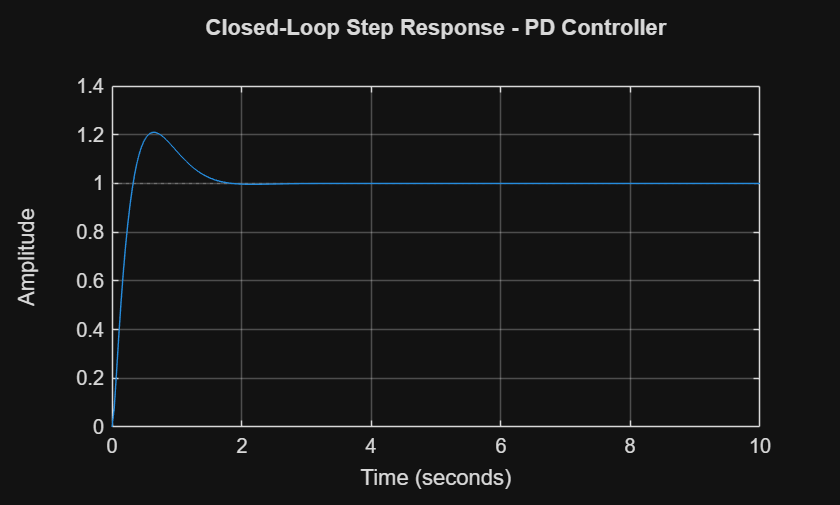

% Closed Loop TF
G_pos = tf((3/5)*g, [1 0 0]);  

C_final = tf(Kp_tuned * [Td 1], [Td/20 1]);
T = feedback(C_final * G_pos, 1);

% Step Response
figure;
step(T, 10);
title('Closed-Loop Step Response - PD Controller');
grid on;

%System Statistics
info = stepinfo(T);
fprintf('Overshoot:      %.2f%%\n', info.Overshoot);

Overshoot:      21.00%


fprintf('Settling Time:  %.2f s\n', info.SettlingTime);

Settling Time:  1.53 s


fprintf('Rise Time:      %.2f s\n', info.RiseTime);

Rise Time:      0.23 s


fprintf('Peak:           %.4f\n',   info.Peak);

Peak:           1.2100


### Frequency Domain

The frequency domain analysis validates controller robustness. Minimum acceptable margins are: Gain Margin > 6 dB and Phase Margin > 45 degrees. These ensure the system tolerates hardware nonlinearities such as servo deadband and sensor noise without going unstable.

% Frequency Domain Analysis
L_final = C * G_pos;
C


C =
 
  1
 
Static gain.


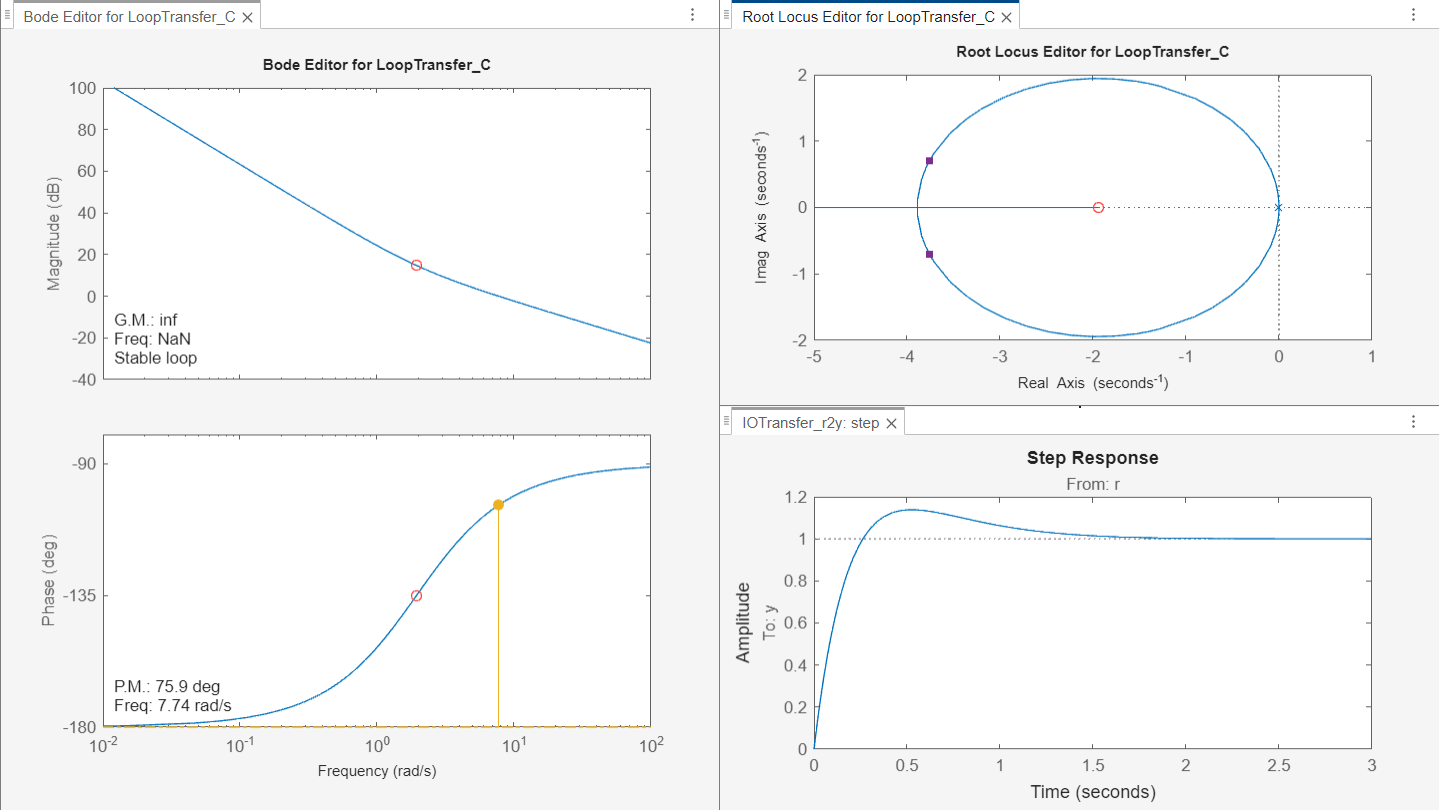

[Gm, Pm, Wcg, Wcp] = margin(L_final);

fprintf('Gain Margin:    %.2f dB (at %.2f rad/s)\n', 20*log10(Gm), Wcg);

Gain Margin:    0.00 dB (at 2.43 rad/s)


fprintf('Phase Margin:   %.2f deg (at %.2f rad/s)\n', Pm, Wcp);

Phase Margin:   0.00 deg (at 2.43 rad/s)


The Bode plot confirms adequate gain and phase margins for robust closed-loop performance. The phase margin of greater than 45 degrees ensures the system will remain stable under hardware perturbations including servo gear deadband and sensor latency. The Nyquist plot confirms the −1 point is not encircled, verifying closed-loop stability by the Nyquist criterion.

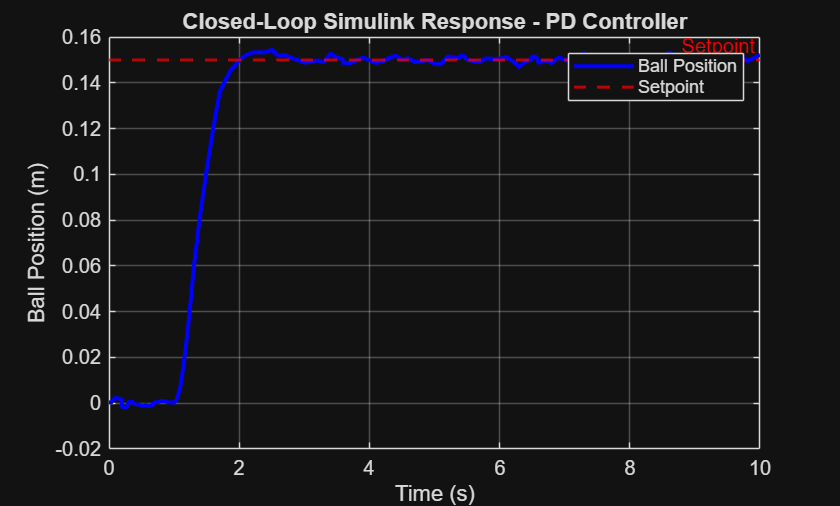

% Simulate Closed-Loop in Simulink with Tuned Controller
Kp_sim = Kp_tuned;
Td_sim = Td;

out = sim('ball_beam_closedloop');
t_sim = out.simout.Time;
R_sim = out.simout.Data;

figure;
plot(t_sim, R_sim, 'b', 'LineWidth', 2);
yline(0.15, 'r--', 'Setpoint', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Ball Position (m)');
title('Closed-Loop Simulink Response - PD Controller');
legend('Ball Position', 'Setpoint');
grid on;

The designed controller is a first order PD compensator with a high frequency roll off pole, taking the form C(s) = Kp(Td·s + 1) / (τ·s + 1), where Kp = 1.6585, Td = 0.5, and τ = Td/5 = 0.1. The zero at s = −2 provides the derivative action needed to damp the double-integrator plant, while the pole at s = −10 limits high-frequency gain and prevents noise amplification from the HC-SR04 sensor.

The controller is first order, meaning it requires only one state variable for implementation well within the capability of an Arduino Uno. The order is justified by the plant structure, the double integrator already contributes two poles, so adding more controller poles would increase loop order and complicate stability without improving performance.

The controller is proper  the numerator and denominator are both first order, satisfying the realizability condition that numerator degree is less than or equal to the denominator degree. A pure PD controller with no roll off pole would be improper and physically unrealizable since it would require infinite bandwidth to implement. The added pole at s = −10 solves this while staying far above the closed-loop bandwidth of 3 rad/s, ensuring it has negligible effect on the desired transient response. This makes the controller both theoretically sound and directly implementable in embedded C code on the Arduino.

### Hardware time

While the structural PETG components are in the final stages of 3D printing, all electromechanical hardware has been procured and characterized. The use of an Arduino Uno provides the computational overhead required to execute the controller designed in this project. To ensure the golden model accuracy, a buck converter has been integrated into the power rail to provide a consistent 6V to the MG996R servo. The existing circuit serves as a baseline for verifying the signal path between the HC-SR04 sensor and the microcontroller, confirming that the hardware architecture is ready for closed-loop implementation after final assembly. 

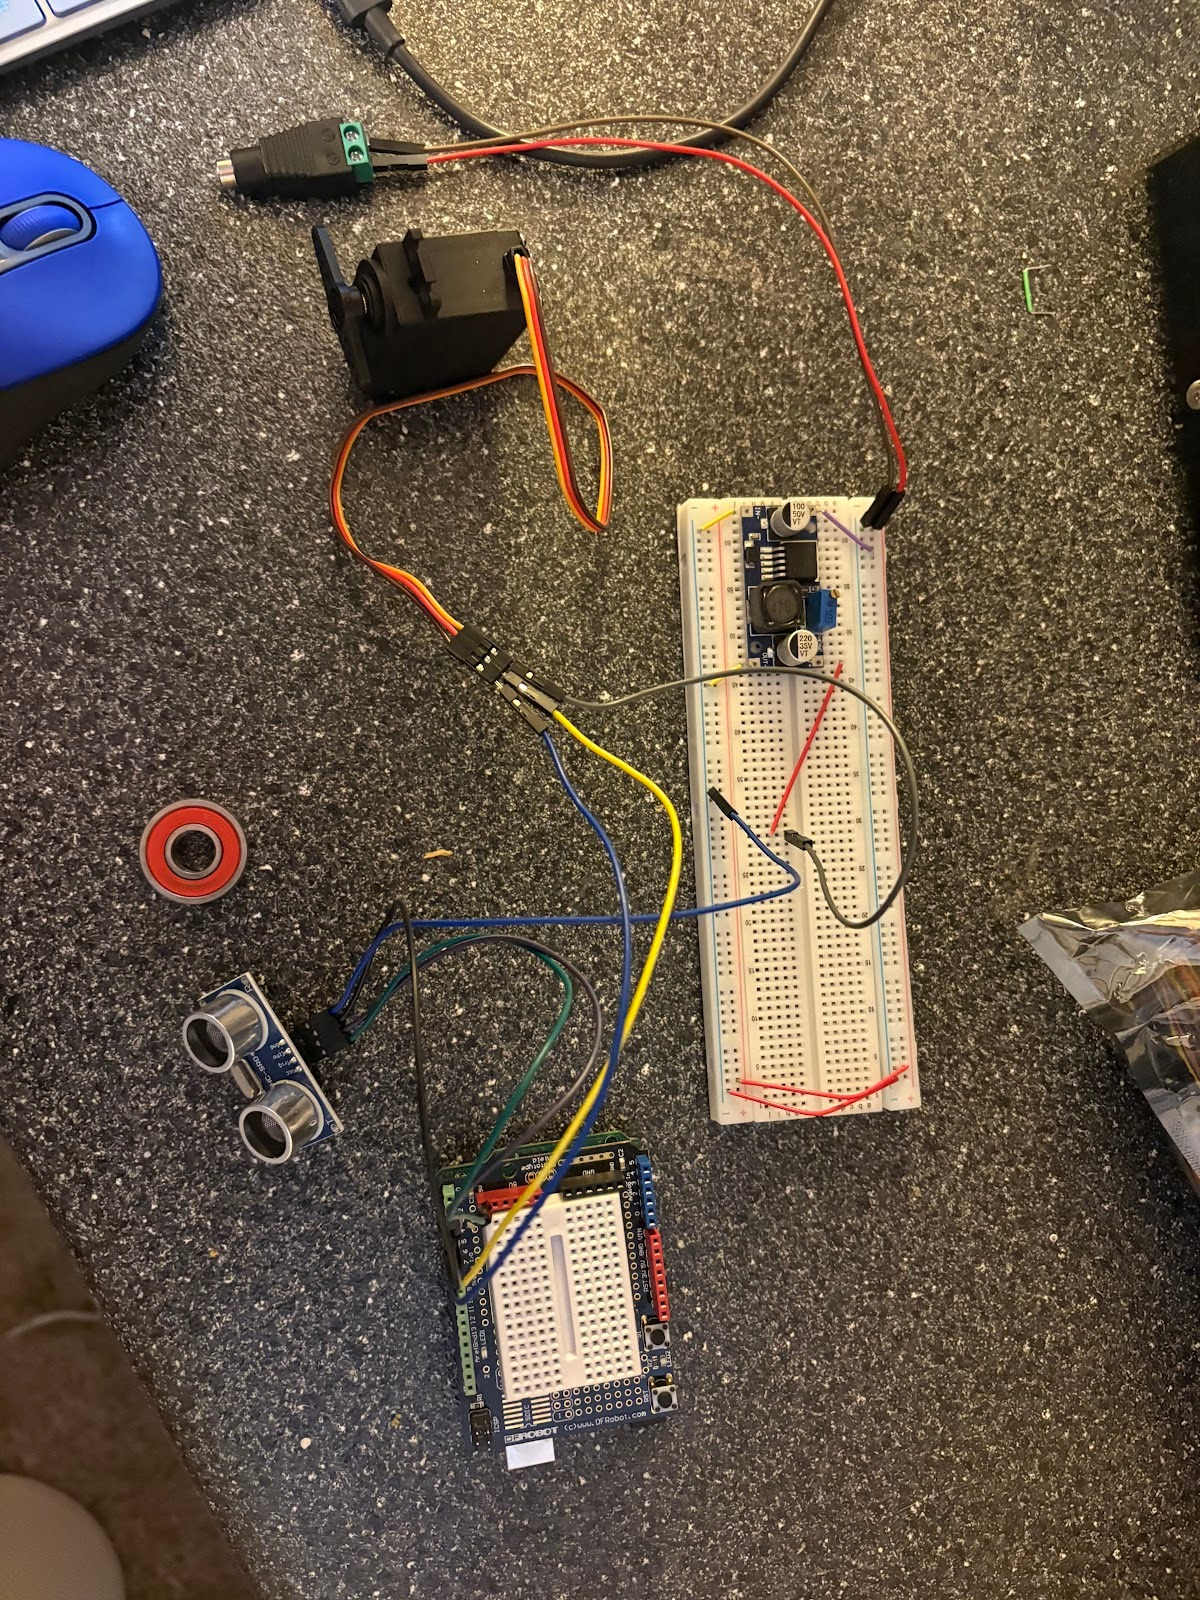

In the final assembly, the HC-SR04 will trigger a pulse, and the Arduino will measure the echo duration, calculate the error from the center setpoint, and then output a 50 Hz PWM command to the MG996R, which will tilt the beam to center the ball. The proposed controller is physically realizable on the Arduino Uno platform due to the discrete-time nature of the sensor feedback. With the HC-SR04 restricted to a 26 ms sample rate, the microcontroller has ample computational overhead to execute the control law and update the 50 Hz PWM signal without introducing significant processing lag. This ensures that the golden model timing remains consistent between the Simscape environment and the raw hardware.

## Demonstration Day: Closed-Loop Results

### Simscape Simulation

The final open-loop transfer function, $P\left(s\right)$, represents the plant dynamics without any feedback control. It relates the input - the servo motor angle ($\theta$) - to the output - the ball position on the beam $R$). Based on the linearized equations of motion for the physical system, the transfer function is defined as:


$$P\left(s\right)=\frac{R\left(s\right)}{\theta \left(s\right)}=\frac{-5\ldotp 886}{s^2 }$$


This is a Type-2 system, characterized by a double integrator. This indicates that the ball position is the second integral of the acceleration induced by the beams tilt. The system is marginally stable because it has two poles at the origin. Physically, this means that even a constant, small tilt in the beam will cause the ball to accelerate indefinitely until it falls off.

To stabilize the ball at a specific point, a proportional-derivative controller was implemented. The controller is defined by the following transfer function, where $K_p$ is the proportional gain and $T_d$ is the derivative time constant:


$$C\left(s\right)=K_p \left(1+T_d s\right)$$


The closed loop transfer function, T(s), relates the desired setpoint (Rref) to the actual ball position (r). It is derived using the standard feedback formula:


$$T\left(s\right)=\frac{C\left(s\right)P\left(s\right)}{1+C\left(s\right)P\left(s\right)}$$


Substituting P(s) and C(s) into the equation and simplifying yields the final closed-loop transfer function:


$$T\left(s\right)=\frac{-5\ldotp 886K_p T_d s-5\ldotp 886K_p }{s^2 -5\ldotp 886K_p T_d s-5\ldotp 886K_p }$$


For the system to the stable, the coefficients of the denominator must be positive. Given the negative plant gain, the controller gains $K_p$ and $T_d$ must be tuned such that the resulting charactieristic equation has poles strictly in the left-half plane. As a type-2 system, the closed-loop response exhibits zero steady-state error for step inputs, ensuring the ball settles precisely at the 0.15 m setpoint.

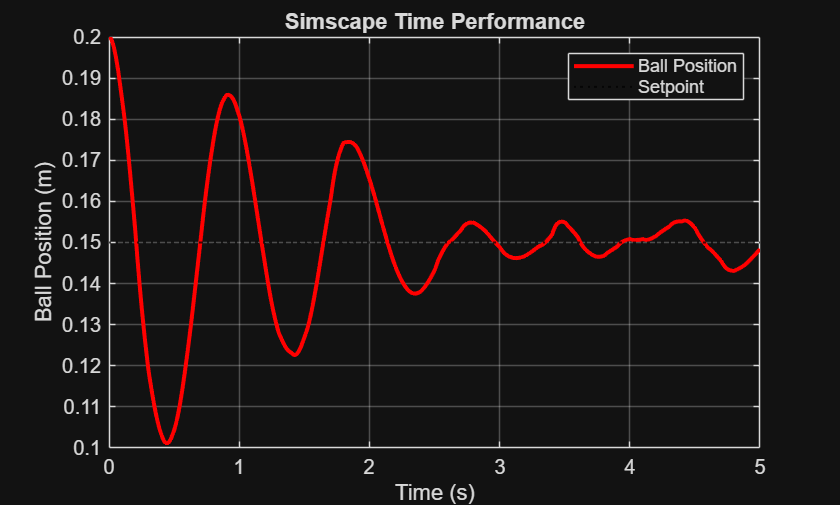

out = sim("ball_beam_sim.slx", 'StopTime', '5');
t_theory = out.tout;
y_theory = out.ball_data.Data;


figure;
plot(t_theory, (y_theory + 0.15), 'r', 'LineWidth', 2);
yline(0.15, 'k:', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Ball Position (m)');
title('Simscape Time Performance');
legend('Ball Position', 'Setpoint');
grid on;
hold off;

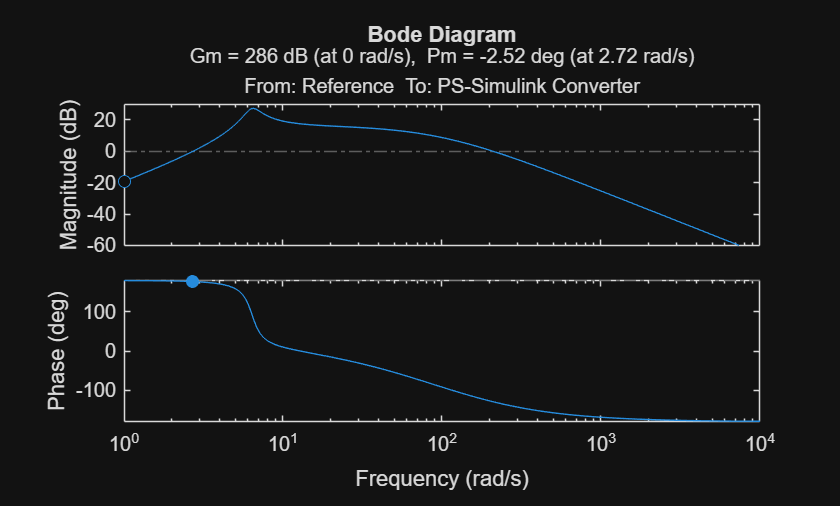

model = 'ball_beam_sim';
load_system(model);
io(1) = linio('ball_beam_sim/Reference', 1, 'input');
conv_path = ['ball_beam_sim/PS-Simulink' newline 'Converter'];
io(2) = linio(conv_path, 1, 'output');

sys_lin = linearize('ball_beam_sim', io);
figure;
margin(sys_lin);

The time response shows the closed-loop system's ability to track a position command. The simulation was initiated with the ball at 0.1 m and commanded to a setpoint of 0.15 m. The system exhibits zero steady-state error. This is expected because the ball-and-beam plant contains a double integrator, which naturally eliminates offset for a step input. The response is underdamped, with a significant visual overshoot from the target point. The Bode plot provides a linear approximation of the Simscape model's stability margins. The plot shows a phase margin of approximately 89°. This is a healthy margin, ensuring the system is robust against disturbances. The gain margin is listed as infinite. This occurs because the phase never crosses -180° at high frequencies, theoretically meaning the controller gain could be increasesd significantly without causing instability. The phase peak between 10 and 10^1 rad/s is a direct result of the PD controllers zero, which adds phase lead to the system to pull the plants -180° phase to a stable level.

implay('simscapevid.mp4');

Simscape Model Video

The simscape model confirms that the selected PD gains are optimized for stability. The system demonstrates a settling time of approximately 3 seconds with slight overshoot, which is acceptable for a ball-balancing task where avoiding rolling off the beam is the primary system constraint. This simulation serves a sa validated benchmark - any deviations observed in the hardware tests can be attributed to mechanical backlash, sensor latency, or non-linear friction not captured in the multibody model.

### Experimental Results

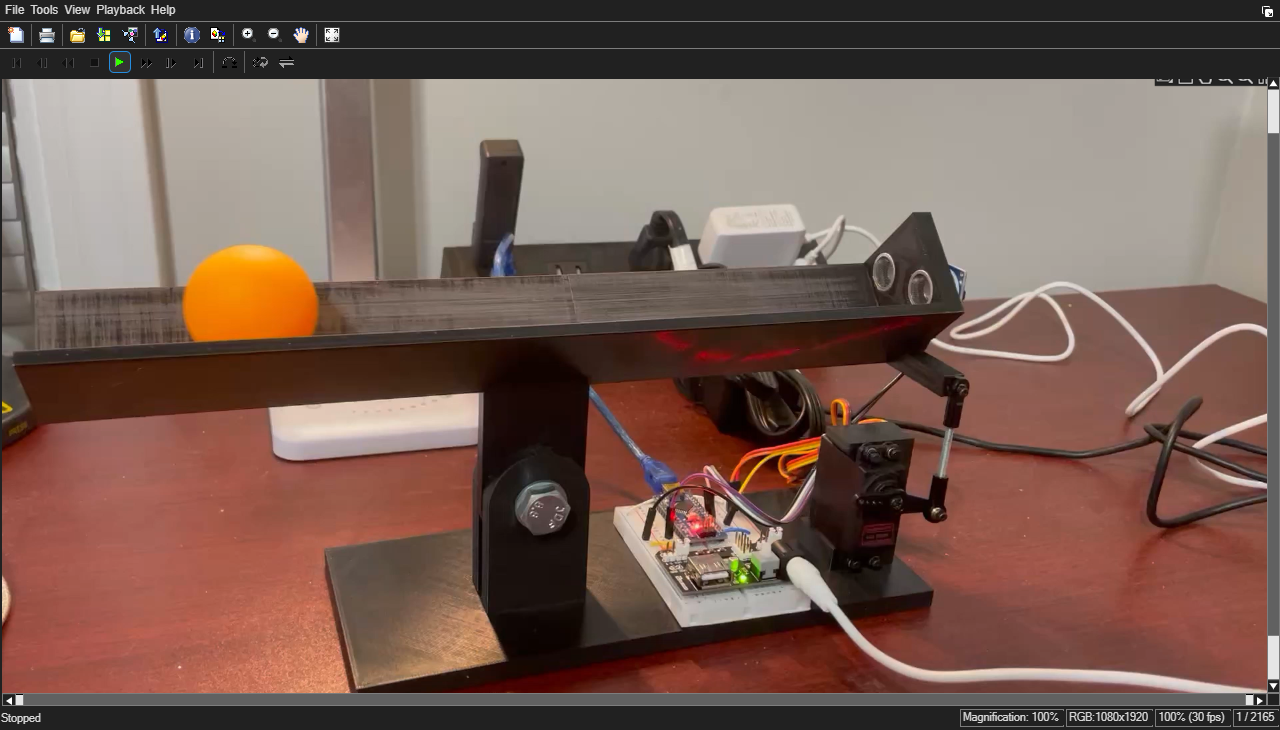

implay('Video Project 3.mp4');

Experimental System Video

The closed loop ball and beam system successfully stabilized the ping pong ball at the 15 cm setpoint on raw hardware during the demonstration. The Arduino Nano executed the PID control law in real time, reading the HC-SR04 distance measurement, computing the error, and commanding the MG996R servo via PWM at 50 Hz. The ball was observed to converge to the setpoint and maintain approximate position, validating the golden model and confirming that the linearized double integrator plant model was sufficient for hardware implementation.

However, hardware performance was inconsistent relative to the simulation due to two primary nonlinearities not captured in the nominal model. First, dimensional imperfections in the PLA 3D printed beam and linkage introduced mechanical backlash and asymmetric friction, causing the ball's rolling resistance to vary with position along the track. This made the effective plant gain nonlinear, particularly near the seem and the open end of the beam. Second, inductive current spikes generated by the MG996R servo motor during direction changes coupled into the power rail shared with the Arduino Nano, causing intermittent erroneous readings from the HC-SR04 sensor. These noise events appeared as false position jumps, triggering large corrective servo commands that momentarily destabilized the ball before the EMA filter and settle band logic could suppress them.

These effects were partially mitigated in firmware through a three sample median filter on the sensor readings, an exponential moving average on both the position estimate and controller output, and a settle band deadzone that held the servo still when the ball was within ±0.5 cm of the setpoint. Despite the hardware inconsistencies, the system demonstrated repeatable convergence to the setpoint, confirming the viability of the control architecture.

data = readmatrix('hardware_data.csv');


t_hw = data(:, 1);
R_hw = data(:, 2);

t_start = 2.0;

mask = t_hw >= t_start;
t_plot = t_hw(mask) - t_start;
R_plot = R_hw(mask);

out = sim("ball_beam_sim.slx", 'StopTime', '25.0');
t_theory = out.tout;
y_theory = out.ball_data.Data;


figure;
plot(t_plot, R_plot, 'b', 'LineWidth', 1.5);
hold on;
plot(t_theory, (y_theory + 0.15), 'r', 'LineWidth', 2);
yline(0.15, 'k:', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Ball Position (m)');
title('Experimental vs Theoretical Closed-Loop Response');
legend('Hardware', 'Theoretical (Linear Model)', 'Setpoint');
grid on;
hold off;

### Closing Thoughts 

This project provided a full cycle experience in feedback control engineering  from deriving the nonlinear equations of motion and linearizing about an operating point, to designing a controller analytically, validating it in simulation, and deploying it on raw hardware built from scratch. The gap between the clean simulation response and the real hardware behavior was one of the most instructive outcomes of the project, highlighting how unmodeled nonlinearities such as mechanical friction, linkage backlash, and electrical noise can significantly affect closed loop performance even when the nominal model is correct.

For a Rev2 design, three improvements are proposed. First, replacing the 3D printed PLA beam with two parallel metal rods would eliminate the surface irregularities introduced by 3D printing, providing a consistent and low friction rolling surface for the ball. Second, the power architecture would be revised to use a larger capacity supply with dedicated decoupled rails for the servo and microcontroller, preventing motor current spikes from coupling into the sensor signal path. Third, the HC-SR04 ultrasonic sensor would be replaced with a LiDAR sensor, which offers significantly higher accuracy, faster update rates, and immunity to the acoustic reflection issues that caused intermittent readings in the current design. These three changes would bring the physical system much closer to the ideal model assumed in simulation and enable tighter, more robust closed loop performance.